BL.AI.U4AID25064

Sudarshan Rao

Lab Exercise - 4

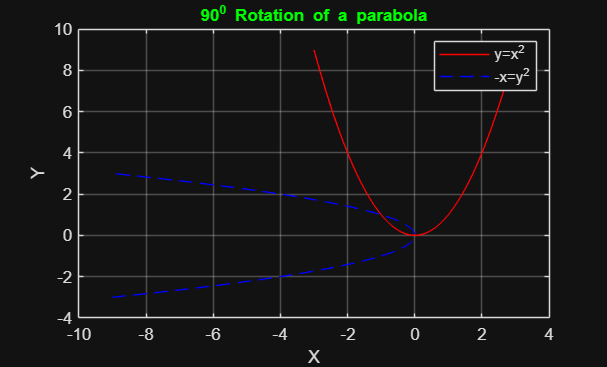

clf
t=-3:0.1:3;
x=[t;t.^2];
plot(t,t.^2,'r-','MarkerSize',10)
hold on
A=[0 -1;1 0]
y=A*x;
plot(y(1,:),y(2,:),'--b','MarkerSize',10)
hold off
grid on
axis ([-10 4 -4 10])
xlabel('X')
ylabel('Y')
legend('y=x^2','-x=y^2')
title('90^0 Rotation of a parabola','color','g','FontSize',10)

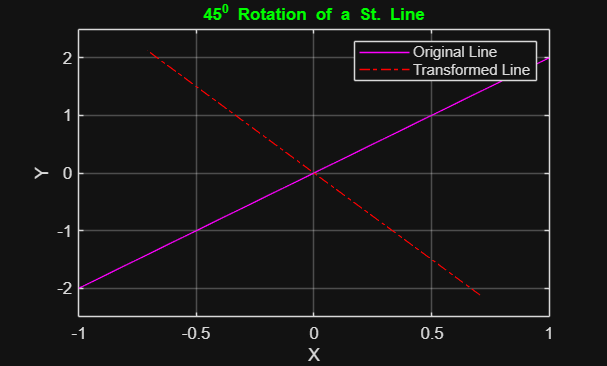

clear
clf
t=-1:0.05:1;
plot(t,2*t,'m','linestyle','-','Markersize',10)
x=[t;2*t];
hold on
A=[1/sqrt(2) -1/sqrt(2);1/sqrt(2) 1/sqrt(2)];
y = A * x;
plot(y(1,:), y(2,:), 'r-.', 'MarkerSize', 10);
hold off
grid on
axis ([-1 1 -2.5 2.5])
xlabel('X')
ylabel('Y')
legend('Original Line','Transformed Line')
title('45^0 Rotation of a St. Line','color','g','FontSize',10)

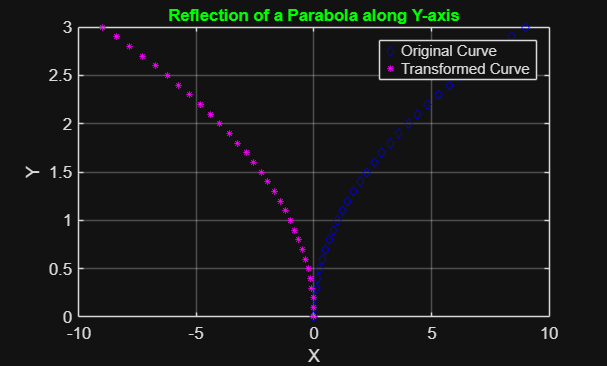

clear
t=0:0.1:3;
plot(t.^2,t,'db','MarkerSize',4)
x=[t.^2;t];
A=[-1 0;0 1];
hold on
y = A * x;
plot(y(1,:), y(2,:), 'm*', 'MarkerSize', 4)
hold off
grid on
xlabel('X')
ylabel('Y')
legend('Original Curve','Transformed Curve')
title('Reflection of a Parabola along Y-axis','color','g','FontSize',10)

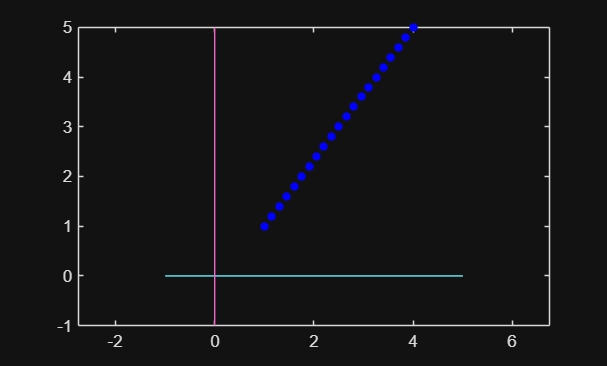

clear
clf
A=[1;1];
B=[4;5];
for lamda=0:0.05:1
x=(1-lamda)*A+(lamda)*B;
plot(x(1,1),x(2,1),'b.','MarkerSize',15)
pause(0.05)
hold on
axis equal
plot([-1,5],[0,0])
plot([0,0],[-1,5])
drawnow
end

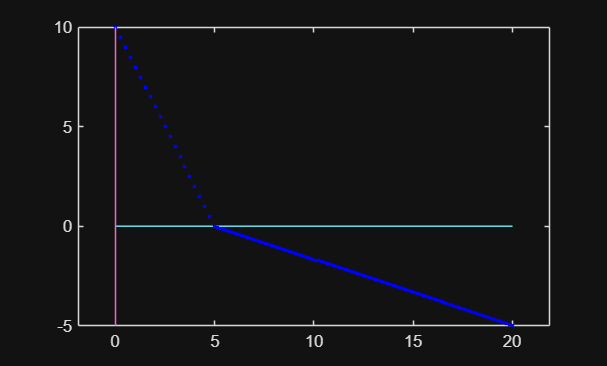

clear
clf
XO=[0;10];
XM=[5;0];
XE=[20;-5];
for i=0:0.05:1
    x=(1-i)*XO+i*XM;
    plot(x(1,1),x(2,1),'b.','LineWidth',10)
    hold on
    axis equal
    pause(0.05)
    plot([0,20],[0,0])
    plot([0,0],[-5,10])
    drawnow
end
for j=0:0.01:1
    X=(1-j)*XM+j*XE;
    plot(X(1,1),X(2,1),'b.','LineWidth',10)
    hold on
    pause(0.05)
    drawnow
end

Practise Questions:

1Q)

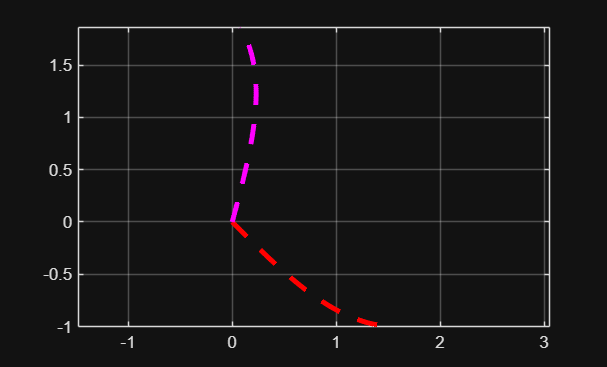

clear
clf
t=linspace(0,pi/2,100);
x=[t;-sin(t)];
plot(x(1,:),x(2,:),'r--','LineWidth',3)
hold on
A=[-1/2 -sqrt(3)/2;sqrt(3)/2 -1/2];  %120 deg rotation matrix
y1=A*x;
plot(y1(1,:),y1(2,:),'m--','LineWidth',3)
axis equal
grid on
hold off

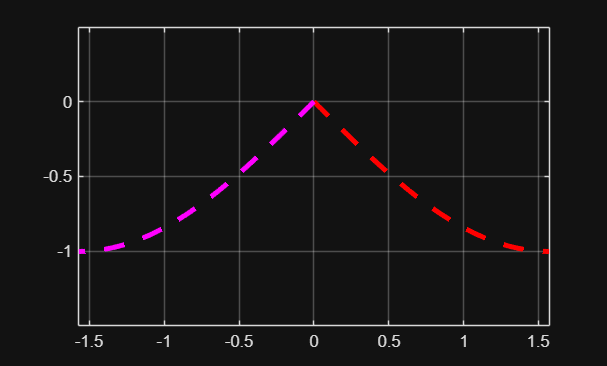

plot(x(1,:),x(2,:),'r--','LineWidth',3)
hold on
B=[-1 0;0 1];  %Reflection about Y-axis
y2=B*x;
plot(y2(1,:),y2(2,:),'m--','LineWidth',3)
axis equal
grid on
hold off

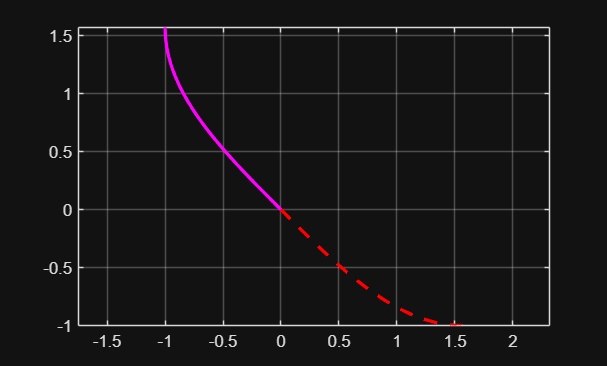

plot(x(1,:),x(2,:),'r--','LineWidth',2)
hold on
C=[0 1;1 0];  %Reflection about y=x line
y3=C*x;
plot(y3(1,:),y3(2,:),'m-','LineWidth',2)
axis equal
grid on
hold off

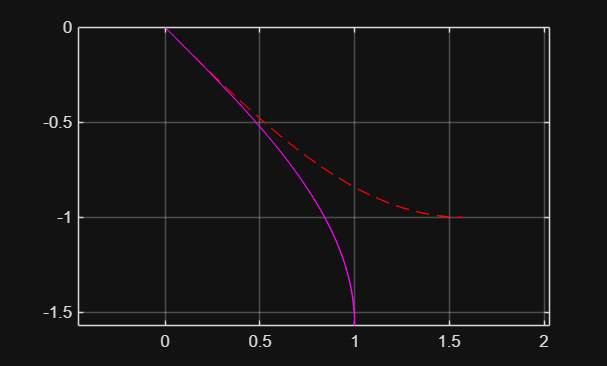

plot(x(1,:),x(2,:),'r--')
hold on
D=-[0 1;1 0];  %Reflection about y=-x line
y4=D*x;
plot(y4(1,:),y4(2,:),'m-')
axis equal
grid on
hold off

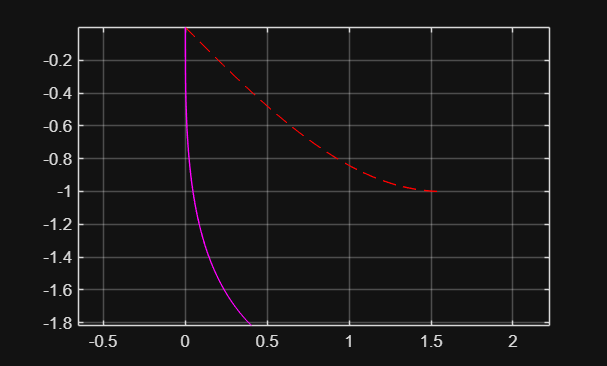

plot(x(1,:),x(2,:),'r--')
hold on
E=[1/sqrt(2) 1/sqrt(2);-1/sqrt(2) 1/sqrt(2)];  %Rotation about 45deg clockwise
y5=E*x;
plot(y5(1,:),y5(2,:),'m-')
axis equal
grid on
hold off

2Q)

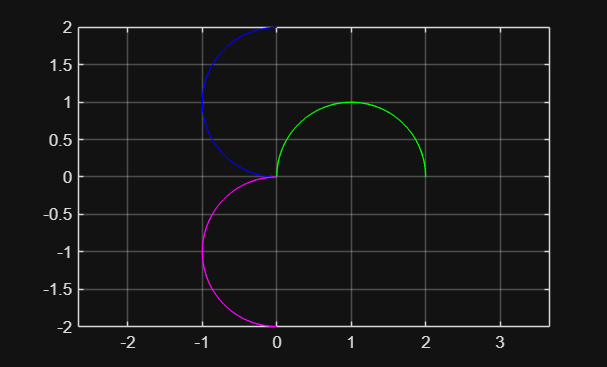

clear
clf
theta=linspace(0,pi,100);
C=[1+cos(theta);sin(theta)];
plot(C(1,:),C(2,:),'g-')
hold on
A=[0 -1;1 0];
C1=A*C;
plot(C1(1,:),C1(2,:),'b-')
axis equal
grid on
B=[1 0;0 -1];
C2=B*C1;
plot(C2(1,:),C2(2,:),'m-')
hold off

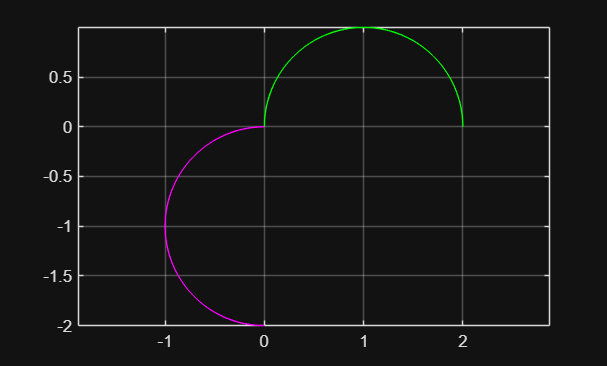

clear
clf
theta=linspace(0,pi,100);
C=[1+cos(theta);sin(theta)];
plot(C(1,:),C(2,:),'g-')
hold on
D=[0 -1;-1 0];
C4=D*C;
plot(C4(1,:),C4(2,:),'m-')
axis equal
grid on
hold off

3Q)

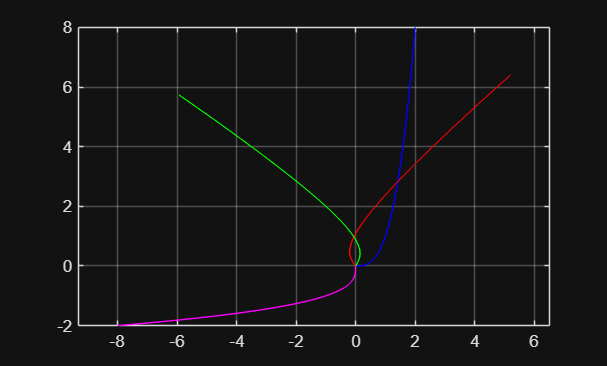

clear
A=[-3/5 4/5;4/5 3/5];
B=[1/2 -sqrt(3)/2;sqrt(3)/2 1/2];
C=[0 -1;-1 0];
t=linspace(0,2,100);
x=[t;t.^3];
plot(x(1,:),x(2,:),'b-')
hold on
y1 = A * x; 
plot(y1(1,:), y1(2,:), 'r-'); % Reflection about line y=2x
y2 = B * x; 
plot(y2(1,:), y2(2,:), 'g-'); % Rotation of axis by 60deg
y3 = C * x; 
plot(y3(1,:), y3(2,:), 'm-'); % Reflection about line y=-x
hold off
axis equal
grid on

4Q)

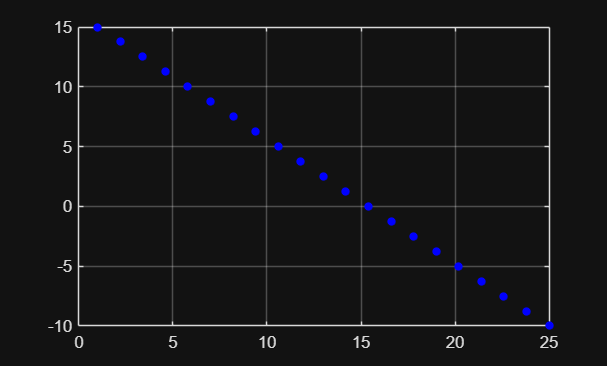

clear
clf
A=[25;-10];
B=[1;15];
for lamda=0:0.05:1
    x=(1-lamda)*A+lamda*B;
    grid on
    axis([0 25 -10 15])
    plot(x(1,1), x(2,1), 'b.', 'MarkerSize', 15);
    pause(0.05)
    hold on
    drawnow;
end
hold off

5Q)

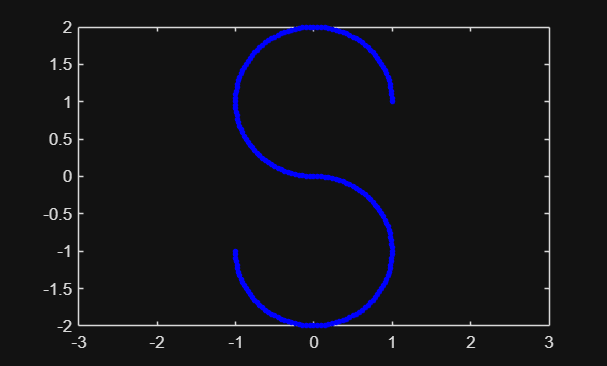

clear
clf
theta1=linspace(-pi/2,pi,100);
C=[1+cos(theta1);sin(theta1)];
A=[0 -1;1 0];
C1 = A * C;
theta2=linspace(pi,-pi/2,100);
D=[1+cos(theta2);sin(theta2)];
B=[0 1;-1 0];
C2=B*D;
for i=1:100
    plot(C1(1,i), C1(2,i),'b.','MarkerSize',10)
    axis([-3 3 -2 2])
    hold on
    pause(0.05)
    drawnow;
end

for j=1:100
    plot(C2(1,j), C2(2,j),'b.','MarkerSize',10)
    hold on
    pause(0.05)
    drawnow;
end
hold off